GFDM parameters

Plot = false;

% Determine where your m-file's folder is.
folder = fileparts(which("opt_problem.mlx")); 
% Add that folder plus all subfolders to the path.
addpath(genpath(folder));

gfdm = struct;
gfdm.K = 8; % Subcarriers
gfdm.M = 7; % Subsymbols

% K_set_temp = 0:gfdm.K-1;
% K_set_shift = circshift(K_set_temp, 2);
% gfdm.K_set = K_set_shift(1:4);
% gfdm.K_set = [7,0,1]; % Used subcarrier index(0 based)
% gfdm.M_set = (1:6);              % Used subsymbol index(0 based). 1 guard subsymbol.
gfdm.K_on = 3;
gfdm.M_on = 6;

% All possible subcarrier and subsymbol index combination (0 based)
gfdm.K_set = nchoosek(0:gfdm.K-1, gfdm.K_on);
gfdm.M_set = nchoosek(0:gfdm.M-1, gfdm.M_on);

gfdm.CP = 0;    % CP length

Es = 1; % Symbol energy

Ts = 10^-6; % Sampling interval

gfdm = GFDM_init(gfdm);

D = gfdm.D;
D_prime = gfdm.D_prime;

Normalized frequency $f$ and normalized frequency interval $\Delta f$

delta_f = 0.01;     % Normalized frequency: f = F/Fs = F/2B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);


Interpolation filter $P(f)$

P = rc_filter(delta_f, f_range, 0.1);

Optimization problem & Dottorro iterative algorithm


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


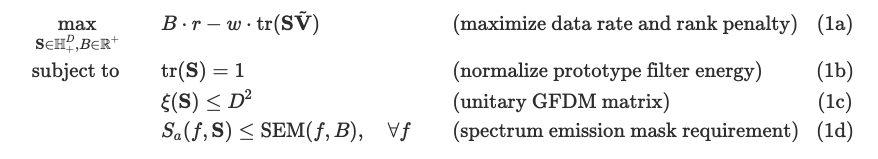

feasible_set = struct;
feasible_set.K = single.empty;
feasible_set.M = single.empty;
for K_set = 1:size(gfdm.K_set, 1)
    fprintf('K_set =');
    gfdm.K_set(K_set, :)

    for M_set = 1:size(gfdm.M_set, 1)
        fprintf('M_set =');
        gfdm.M_set(M_set, :)

        s_2 = 1;
        w = 1;  % Rank 1 penalty
        V_tilde = zeros(D);
        counter = 1;

        while abs(s_2) > 10^-6
            tic
            cvx_begin sdp quiet
            variable S(D, D) hermitian nonnegative semidefinite
            variable K integer
            variable M integer
            expression psd_temp(length(P), 1)

            % SEM
            mask_ac_dB = ac(delta_f, f_range, B);
            mask_ac_linear = db2pow(mask_ac_dB);

            % PSD
            psd = (P.^2) .* PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, gfdm.K_set(K_set, :), gfdm.M_set(M_set, :), gfdm.CP, delta_f, Ts, Es);

            minimize -B + trace(S * V_tilde)   % (1a)
            subject to
            trace(S) == 1;                       % (1b)
            nep_S(S, gfdm.K, gfdm.M) <= D^2;     % (1c)
            psd <= mask_ac_linear;               % (1d)

            cvx_end
            toc

$\tilde{\mathbf{V}}=\mathbf{U}\mathbf{U}^H, \mathbf{U} $ is $\mathbf{Q}$ with first column removed.

$\tilde{\mathbf{V}}$represents the (D-1)-dimensional space orthogonal to the principal eigenvector of $\mathbf{S}$ in the previous iteration.

            try
                [U_svd, S_svd, ~] = svd(S);
            catch ME
                fprintf('Infeasible.\n\n');
                break;
            end

            s_2 = S_svd(2, 2);
            fprintf('%d.s_2 = %f\n\n', counter, s_2);

            U = U_svd(:, 2:end);
            V_tilde = U*U';

            counter = counter + 1;

Plot $S_a(f, \mathbf{S})$ and SEM

            if Plot == 1
                g = U_svd(:, 1) .* sqrt(S(1, 1));
                G = g2chaG(g, gfdm.K, gfdm.M);
                S_a = PSD(G, f_range, gfdm.K, gfdm.M, gfdm.K_set(K_set, :), gfdm.M_set(M_set, :), gfdm.CP, delta_f, Es);
                % mask = max(mask_ac_linear, zeros(size(mask_ac_linear)));
                plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);
            end
        end

        if abs(s_2) < 10^-6
            % Store feasible set
            feasible_set.K = [feasible_set.K; gfdm.K_set(K_set, :)];
            feasible_set.M = [feasible_set.M; gfdm.M_set(M_set, :)];

            g = U_svd(:, 1) .* sqrt(S(1, 1));
            G = g2chaG(g, gfdm.K, gfdm.M);
            S_a = PSD(G, f_range, gfdm.K, gfdm.M, gfdm.K_set(K_set, :), gfdm.M_set(M_set, :), gfdm.CP, delta_f, Es);
            % mask = max(mask_ac_linear, zeros(size(mask_ac_linear)));
            plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);
            text(0.3, 6, ['$K_{on}$[ ' num2str(gfdm.K_set(K_set, :)) ' ]'], 'interpreter','latex');
            text(0.3, 3, ['$M_{on}$[ ' num2str(gfdm.M_set(M_set, :)) ' ]'], 'interpreter','latex');
        end
    end
end

Obtain the GFDM prototype filter $\mathbf{g}$

g = U_svd(:, 1) .* sqrt(S(1, 1));

psd_temp = zeros(size(P));
S_a = PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, gfdm.K_set(K_set, :), gfdm.M_set(M_set, :), gfdm.CP, delta_f, Es);
plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);